% 16-714 Advanced Control for Robotics
% extra credit
% Yutong Huang
clc;clear;
close all;

## Initialization

global robot;
robot = loadrobot('kinovaGen3','DataFormat','row','Gravity',[0 0 -9.81]);

goal = [0.4,0,0.6];
x0 = homeConfiguration(robot);
% joint space x0
x0 = [x0;zeros(1,7)];
endEffector = "EndEffector_Link";
taskInit = getTransform(robot,x0(1,:),endEffector);
taskFinal = trvec2tform(goal)*axang2tform([0 1 0 pi]);
ik = inverseKinematics("RigidBodyTree",robot);
xT = ik(endEffector,taskFinal,[1 1 1 1 1 1],x0(1,:));
xT = mod(xT,2*pi);
% joint space xT (goal)
xT = [xT;zeros(1,7)];

% simple double integrator
Tmax = 5;
dt = 0.05; 
A = [1 dt; 0 1];
B = [0; dt];

% lqr costs x'Qx +u'Ru
Q = [5 0; 0 1];
R = 1;


## Joint space control (lqr)

% find the lqr gain
[K,~] = dlqr(A,B,Q,R);

% function for control gain and rollout
u = @(x) -K*(x-xT);
f = @(x,u) A*x + B*u;

% Simulate Trajectory
tlist = 0:dt:Tmax;
xlist = zeros(size(x0,1),size(x0,2),length(tlist)); 
xlist(:,:,1) = x0; 
ulist = zeros(size(u(x0),2),length(tlist)-1);
for k = 1:length(ulist)
    ulist(:,k) = u(xlist(:,:,k))';
    xlist(:,:,k+1) = f(xlist(:,:,k),ulist(:,k)');
end 


## visualize

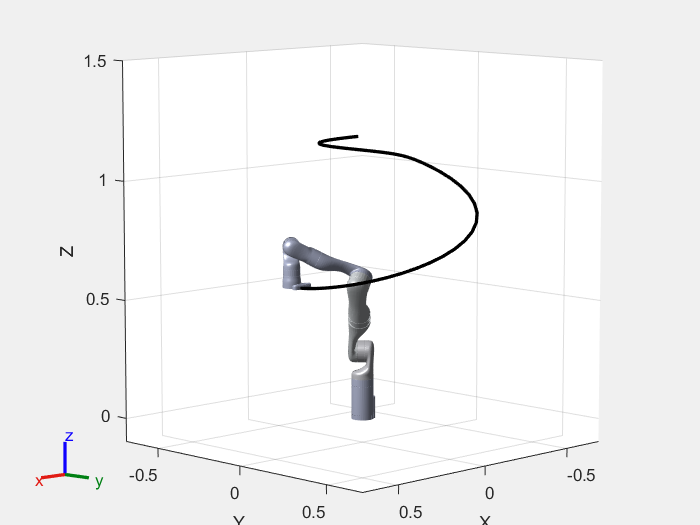

visualize_arm = 0;
figure(1); clf; 
clist = zeros(length(tform2trvec(taskInit)),length(tlist)); 
clist(:,1) = tform2trvec(taskInit)';
for k = 2:length(tlist)
    x = xlist(1,:,k);
    if visualize_arm
        pause(dt);
        show(robot,x,'PreservePlot',true,'Frames','off');
        axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);
    end
    clist(:,k) = tform2trvec(getTransform(robot,x,endEffector))';
end
show(robot,x,'PreservePlot',true,'Frames','off');
axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);
hold on;
plot3(clist(1,:),clist(2,:),clist(3,:),'k','LineWidth',2);
axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);

## plot control tarj

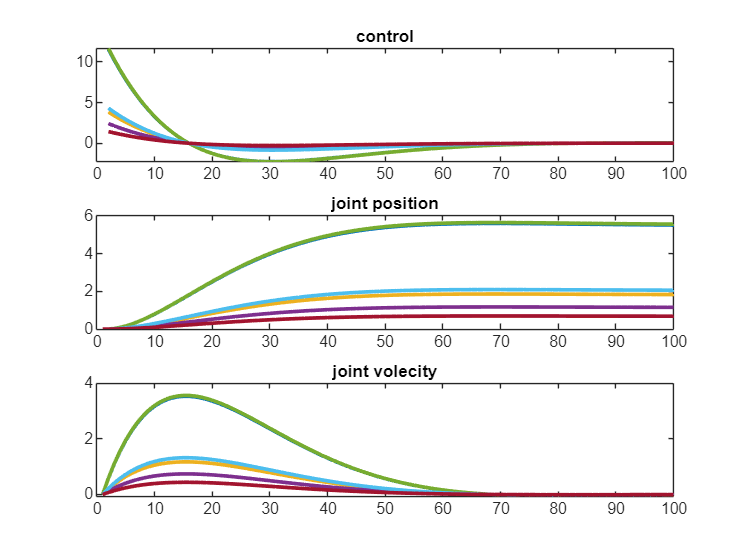

figure(2);
subplot(3,1,1)
plot(2:length(tlist), ulist,'LineWidth',2);
title("control")
xlim([0 100])
subplot(3,1,2)
plist = reshape(xlist(1,:,:), size(xlist,2), size(xlist,3));
plot(1:length(tlist), plist,'LineWidth',2);
title("joint position")
xlim([0 100])
subplot(3,1,3)
vlist = reshape(xlist(2,:,:), size(xlist,2), size(xlist,3));
plot(1:length(tlist), vlist,'LineWidth',2); 
title("joint volecity")
xlim([0 100])

## save the tarj for MPC

save('ref_traj.mat', 'xlist');